% Fractional order proportional derivative controller discretization
% Contact: Bo Shang
% cnpcshangbo@gmail.com

## Impulse response invariant discretization of fractional order

## integrators/differentiators

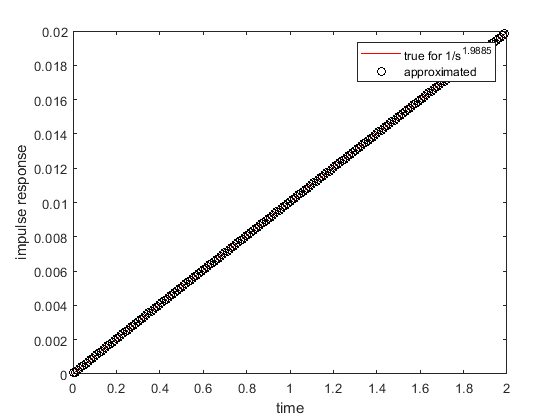

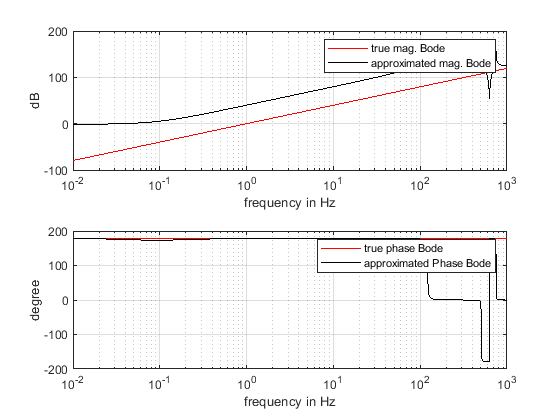

gam=0.9885+1;
Ts=.01;
dfod=irid_fod_Ts(gam,Ts,5); % Try this method

Result:

num: 

[1,-3.83915008336134,5.68830152517571,-4.01123857485582,1.31417664909109,-0.152089532241851]

den:

[8.08505564819526e-07,-2.04449367025327e-06,2.63365621479140e-06,-2.14834792194125e-06,8.91860440440781e-07,-1.22283037538058e-07]

Then use* verify_step_response_irid_1_9_Ts.slx and verify_door_irid_1_9.slx* to verify.

## FOPD

kp=1.5489;
ki=0.8829;
s=tf('s');
cd=kp*(1+ki*c2d(s,Ts,'tustin')*dfod);

K=0.8592; T1=1.0710;
p=K/(T1*s+1)/s;
pd=c2d(p,Ts,'matched');%plant

phiz=cd*pd/(1+cd*pd);% this is to calculate the poles
% this link show how poles determines the vibration: http://www.dcsc.tudelft.nl/~sc4060/transp/discreteNOTES.pdf